# Project Report

## **1. Line Detection**

The first step in our railway obstruction detection project is Line Detection, which aims to accurately identify the rails in each image. Detecting the rails provides a reference framework for subsequent analysis, including the identification of obstacles on the track. 

In this stage, we compare different methods studied in theoretical and lab sessions to determine the most robust approach for line detection under varying lighting and background conditions.

clear; clc; close all;

filenames = {
    './Data/cortada11.png',   ... % 1  - OBSTRUCTED (rocks)
    './Data/Frame1253.jpg',   ... % 2  - clear
    './Data/Frame1291.jpg',   ... % 3  - clear
    './Data/Frame1532.jpg',   ... % 4  - clear (curved)
    './Data/Frame1603.jpg',   ... % 5  - clear (curved)
    './Data/Frame1616.jpg',   ... % 6  - OBSTRUCTED (rocks)
    './Data/image00756.jpg',  ... % 7  - clear (station)
    './Data/image02293.jpg',  ... % 8  - clear (railroad crossing)
    './Data/image04054.jpg',  ... % 9  - OBSTRUCTED (rocks)
    './Data/image04925.jpg',  ... % 10 - clear (dark/tunnel)
    './Data/image06026.jpg',  ... % 11 - clear (tunnel exit)
    './Data/j30.jpg',         ... % 12 - OBSTRUCTED (rocks)
    './Data/l20.jpg',         ... % 13 - OBSTRUCTED (vegetation)
    './Data/l23.jpg',         ... % 14 - OBSTRUCTED (vegetation)
    './Data/p8.jpg',          ... % 15 - OBSTRUCTED (rocks beside track)
};

% Ground truth: 0 = clear, 1 = obstructed
labels = [1, 0, 0, 0, 0, 1, 0, 0, 1, 0, 0, 1, 1, 1, 1];

% Figure titles
descriptions = {
    'Obstructed - rocks',
    'Clear - straight',
    'Clear - straight',
    'Clear - curved',
    'Clear - curved',
    'Obstructed - rocks',
    'Clear - station',
    'Clear - railroad crossing',
    'Obstructed - rocks',
    'Clear - dark tunnel',
    'Clear - tunnel exit',
    'Obstructed - rocks',
    'Obstructed - vegetation',
    'Obstructed - vegetation',
    'Obstructed - rocks beside track',
};

N = length(filenames);

% Cell array accommodates images of different resolutions
images = cell(N, 1);
for i = 1:N
    images{i} = imread(filenames{i});
end

% Class distribution — relevant when interpreting
% classification metrics in later phases.
fprintf('\nTotal images:  %d\n', N);


Total images:  15


fprintf('Clear:         %d\n', sum(labels == 0));

Clear:         8


fprintf('Obstructed:    %d\n', sum(labels == 1));

Obstructed:    7


## 1.1. Grayscale Conversion

Color information is not necessary since rails are primarily distinguished by their shape and intensity contrast with the background. All images were first converted to grayscale, focusing on the analysis of intensity variations

For visualization, we select a subset of representative images, chosen because they represent different scenarios: one is obstructed by rocks, another by vegetation and low brightness, and one is a clear (unobstructed) scene. The grayscale images and their corresponding histogram visualizations are then plotted to analyze the distribution of intensity values in each case. These histograms provide insight into the dynamic range of pixel intensities and reveal whether the images are underexposed, overexposed, or well-balanced. 

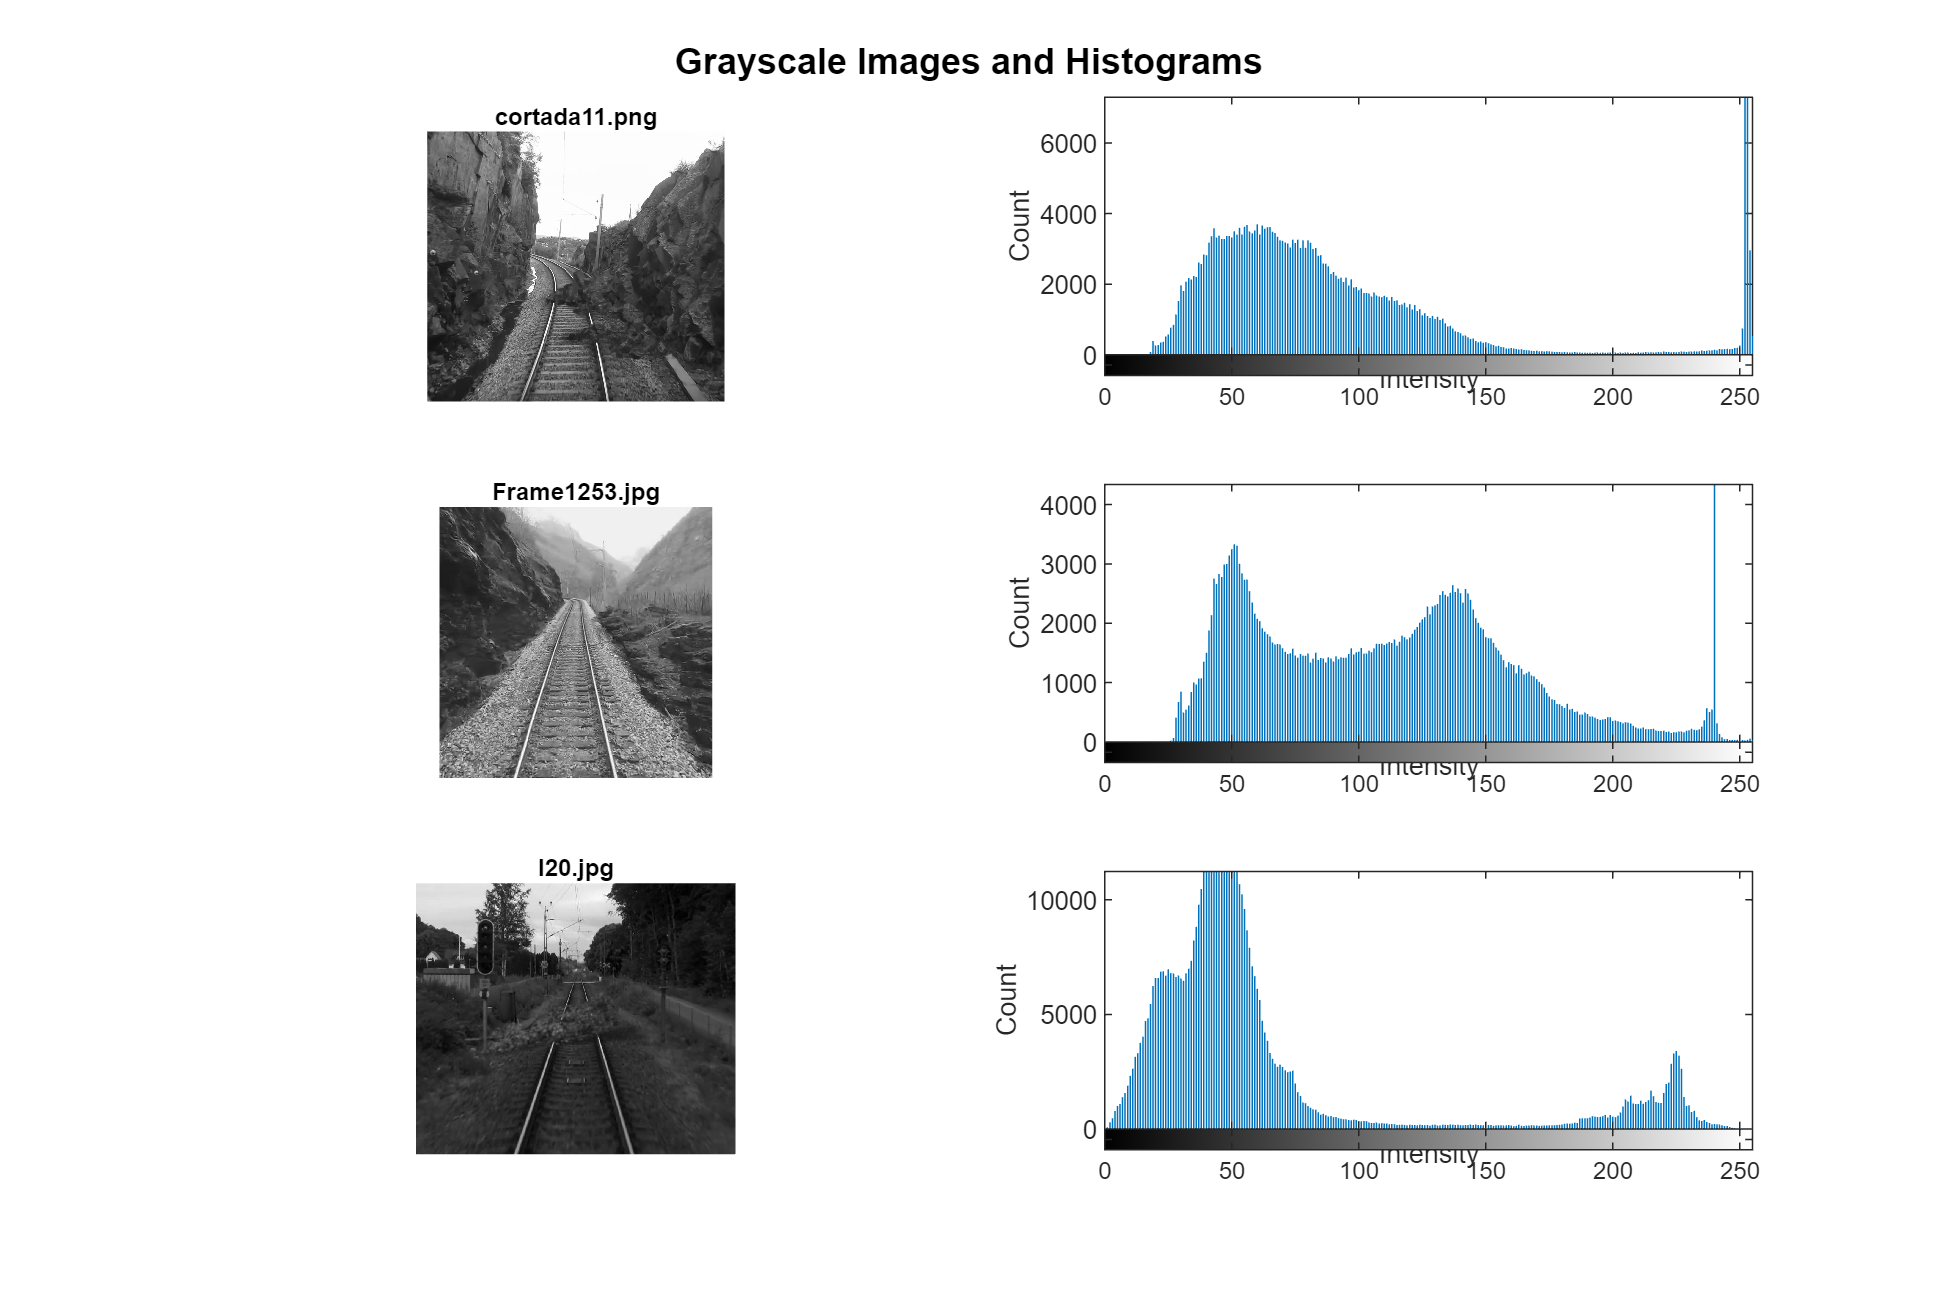

% Convert images to grayscale
images_gray = cell(N, 1);
for i = 1:N
    images_gray{i} = rgb2gray(images{i});
end

% Indices of selected images
SELECTED = [1, 2, 13];
N_plot = numel(SELECTED);

figure('Name', 'Grayscale Images and Histograms (selected)', ...
       'NumberTitle', 'off', 'Position', [100, 100, 1200, 800]);

for k = 1:N_plot
    i = SELECTED(k);

    % Display grayscale image
    subplot(N_plot, 2, (k-1)*2 + 1);
    imshow(images_gray{i});
    [~, name, ext] = fileparts(filenames{i});
    title(sprintf('%s', [name ext]), ...
          'FontSize', 8, 'Interpreter', 'none');

    % Display histogram
    subplot(N_plot, 2, (k-1)*2 + 2);
    imhist(images_gray{i});
    xlabel('Intensity', 'FontSize', 9);
    ylabel('Count', 'FontSize', 9);
end

sgtitle('Grayscale Images and Histograms', ...
        'FontSize', 12, 'FontWeight', 'bold');

The grayscale histograms reveal variations in image intensity and contrast across the dataset. Several images exhibit limited contrast, with pixel values concentrated in a narrow range, which can reduce the effectiveness of edge detection and line identification. These observations indicate that preprocessing steps such as histogram equalization or contrast enhancement are necessary to improve the visibility of rail boundaries

## 1.2. Image Enhancement

To improve the visibility of rails, we tested several image enhancement methods:

- Histogram Normalization

- Histogram Equalization

- Contrast Limited Adaptive Histogram Equalization (CLAHE)

Normalization scales the pixel intensities to the range [0,1]. This process redistributes the pixel values linearly and can sometimes improve contrast. Histogram equalization redistributes pixel intensities to achieve a uniform histogram. This can enhance global contrast and make features more distinguishable. 

CLAHE (Contrast Limited Adaptive Histogram Equalization) enhances image contrast by operating on small local regions rather than the entire image.  Although this method was not covered in class, MATLAB documentation recommends it for improving feature visibility, making it suitable for highlighting rail edges before line detection.

Reference: MATLAB Documentation: *Contrast Limited Adaptive Histogram Equalization*: [https://www.mathworks.com/help/visionhdl/ug/contrast-adaptive-histogram-equalization.html](https://www.mathworks.com/help/visionhdl/ug/contrast-adaptive-histogram-equalization.html#d126e9140)

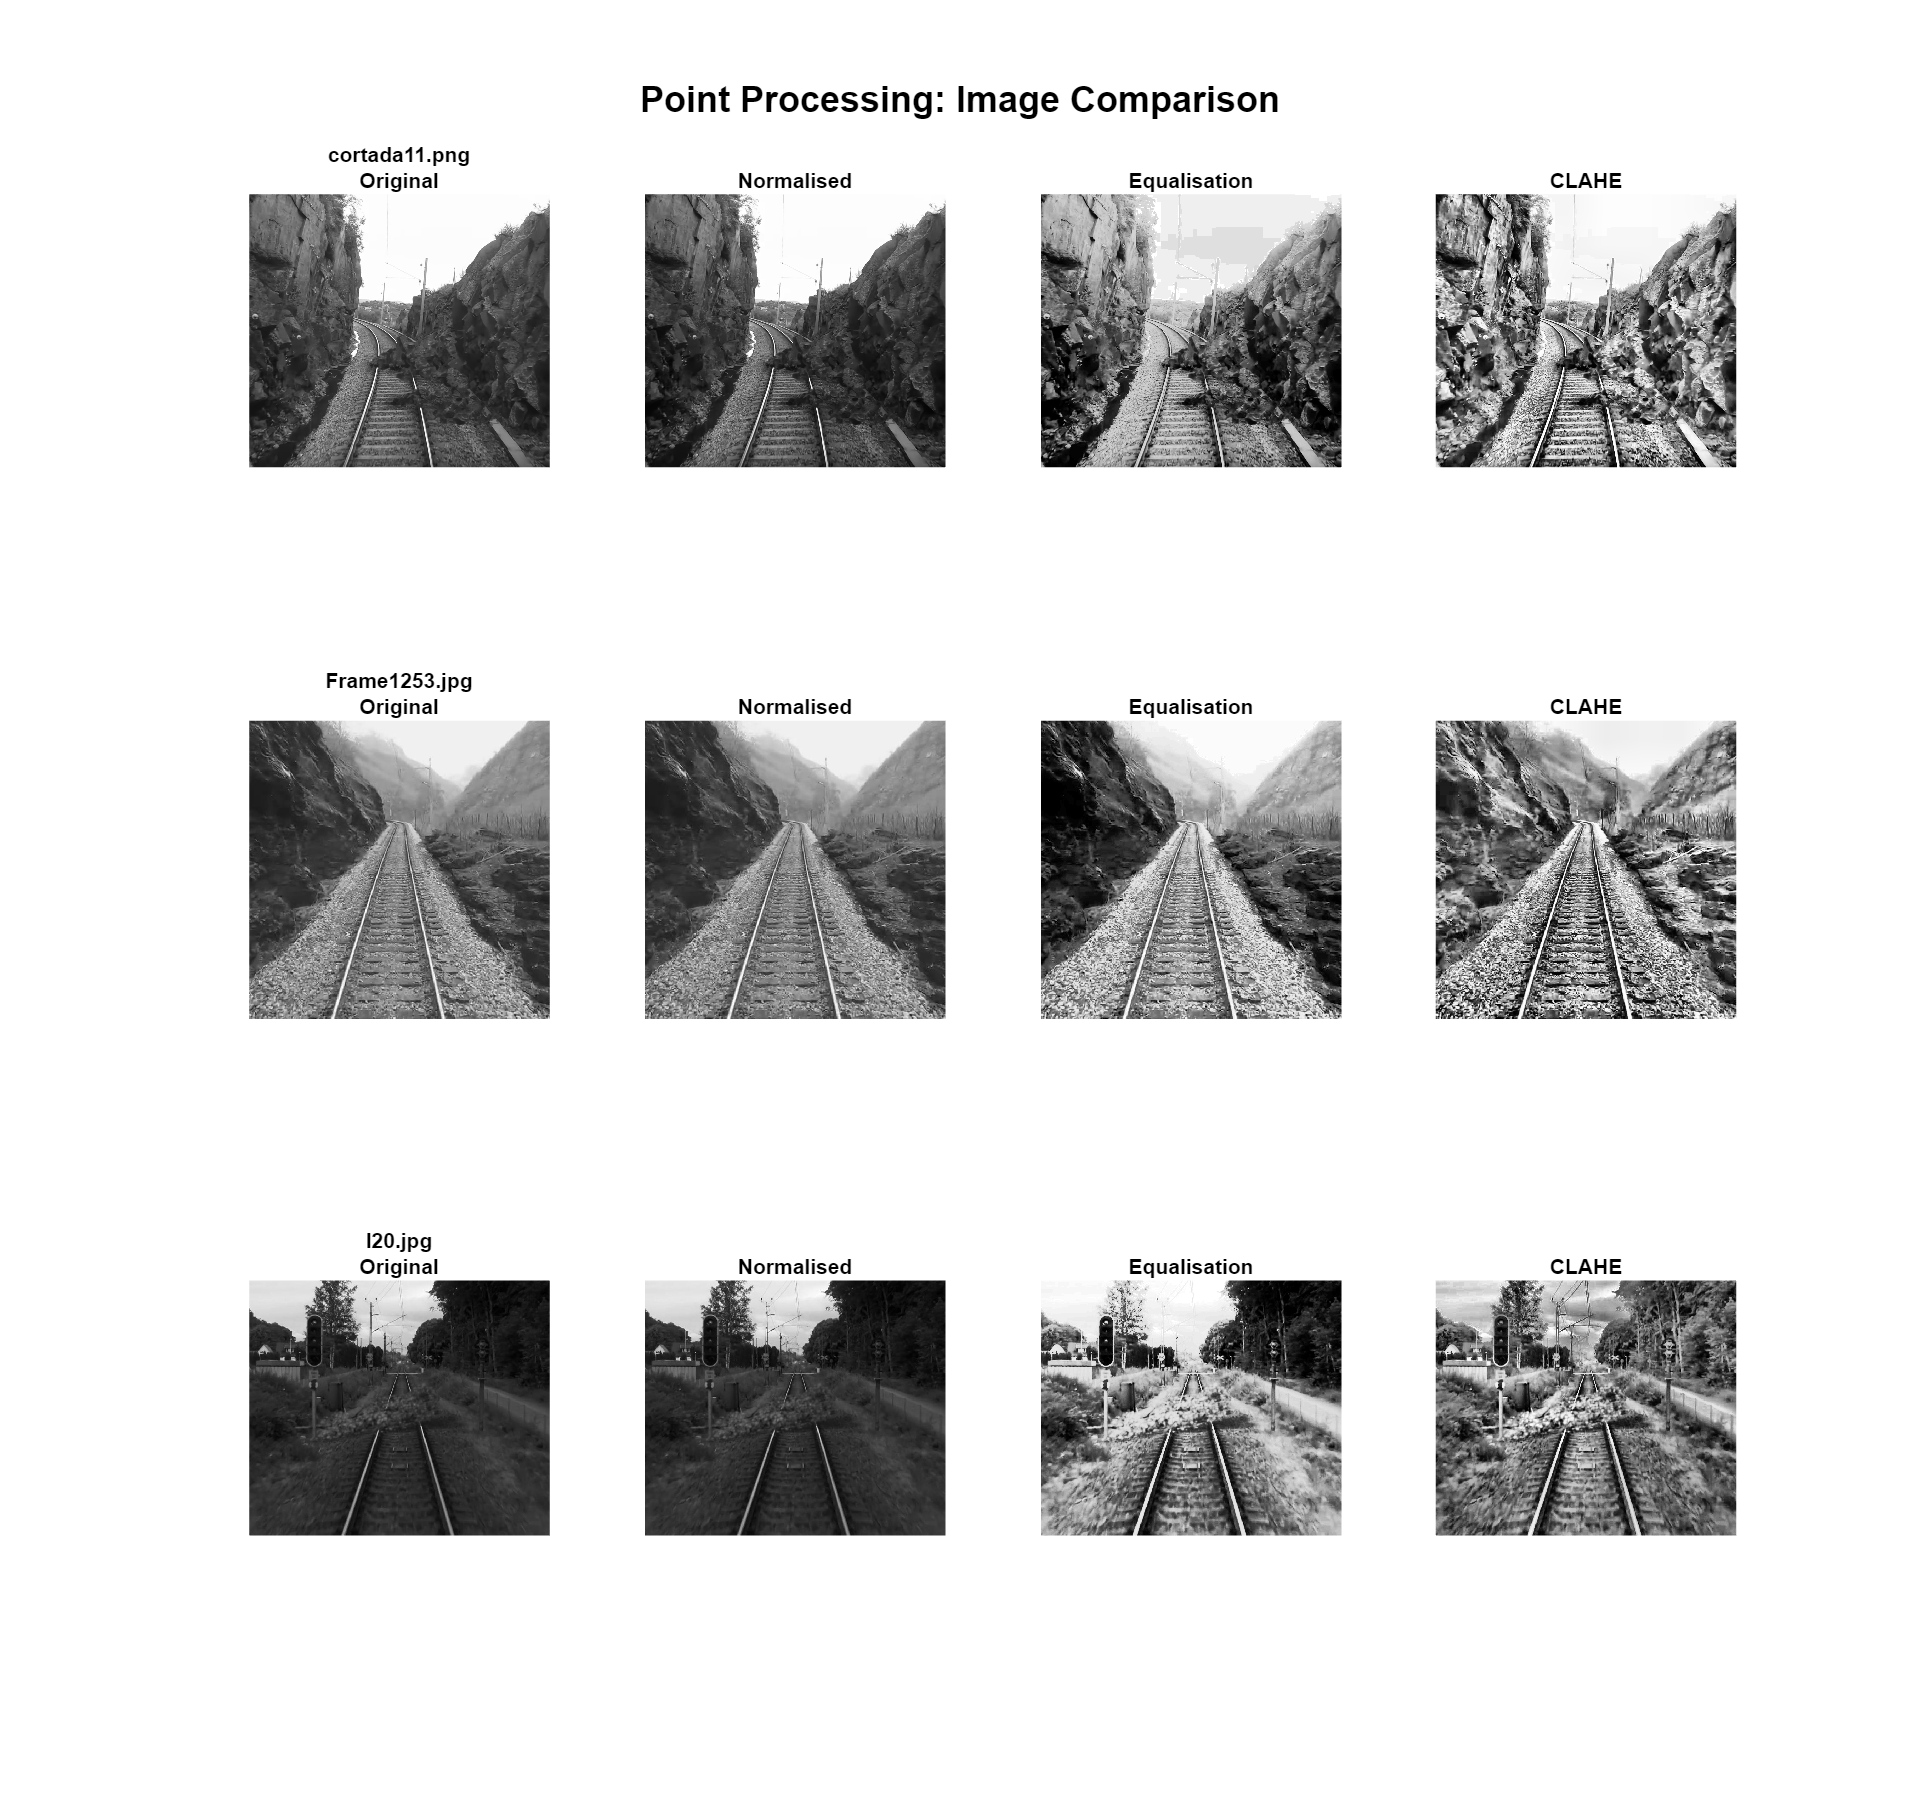

% Parameters
CLAHE_TILES     = [8 8];
CLAHE_CLIPLIMIT = 0.02;

images_norm  = cell(N,1);
images_eq    = cell(N,1);
images_clahe = cell(N,1);

% Process images
for i = 1:N
    img = images_gray{i};

    % Histogram Normalisation
    img_d = double(img);
    images_norm{i} = uint8(255*(img_d - min(img_d(:))) / (max(img_d(:)) - min(img_d(:))));

    % Histogram Equalisation
    images_eq{i} = histeq(img);

    % CLAHE
    images_clahe{i} = adapthisteq(img, ...
                                  'NumTiles', CLAHE_TILES, ...
                                  'ClipLimit', CLAHE_CLIPLIMIT, ...
                                  'Distribution', 'uniform');
end

% Plot Images
figure('Name', 'Point Processing: Images', ...
       'NumberTitle', 'off', 'Position', [0,0,1600,1500]);

for row_disp = 1:length(SELECTED)
    i = SELECTED(row_disp);
    img = images_gray{i};

    [~, name, ext] = fileparts(filenames{i});
    base_title = sprintf('%s', [name ext]);

    % Original
    subplot(length(SELECTED),4,(row_disp-1)*4 + 1);
    imshow(img);
    title(sprintf('%s\nOriginal', base_title), 'FontSize',7,'Interpreter','none');

    % Normalised
    subplot(length(SELECTED),4,(row_disp-1)*4 + 2);
    imshow(images_norm{i});
    title('Normalised','FontSize',7);

    % Equalised
    subplot(length(SELECTED),4,(row_disp-1)*4 + 3);
    imshow(images_eq{i});
    title('Equalisation','FontSize',7);

    % CLAHE
    subplot(length(SELECTED),4,(row_disp-1)*4 + 4);
    imshow(images_clahe{i});
    title('CLAHE','FontSize',7);
end

sgtitle('Point Processing: Image Comparison', ...
        'FontSize',12,'FontWeight','bold');

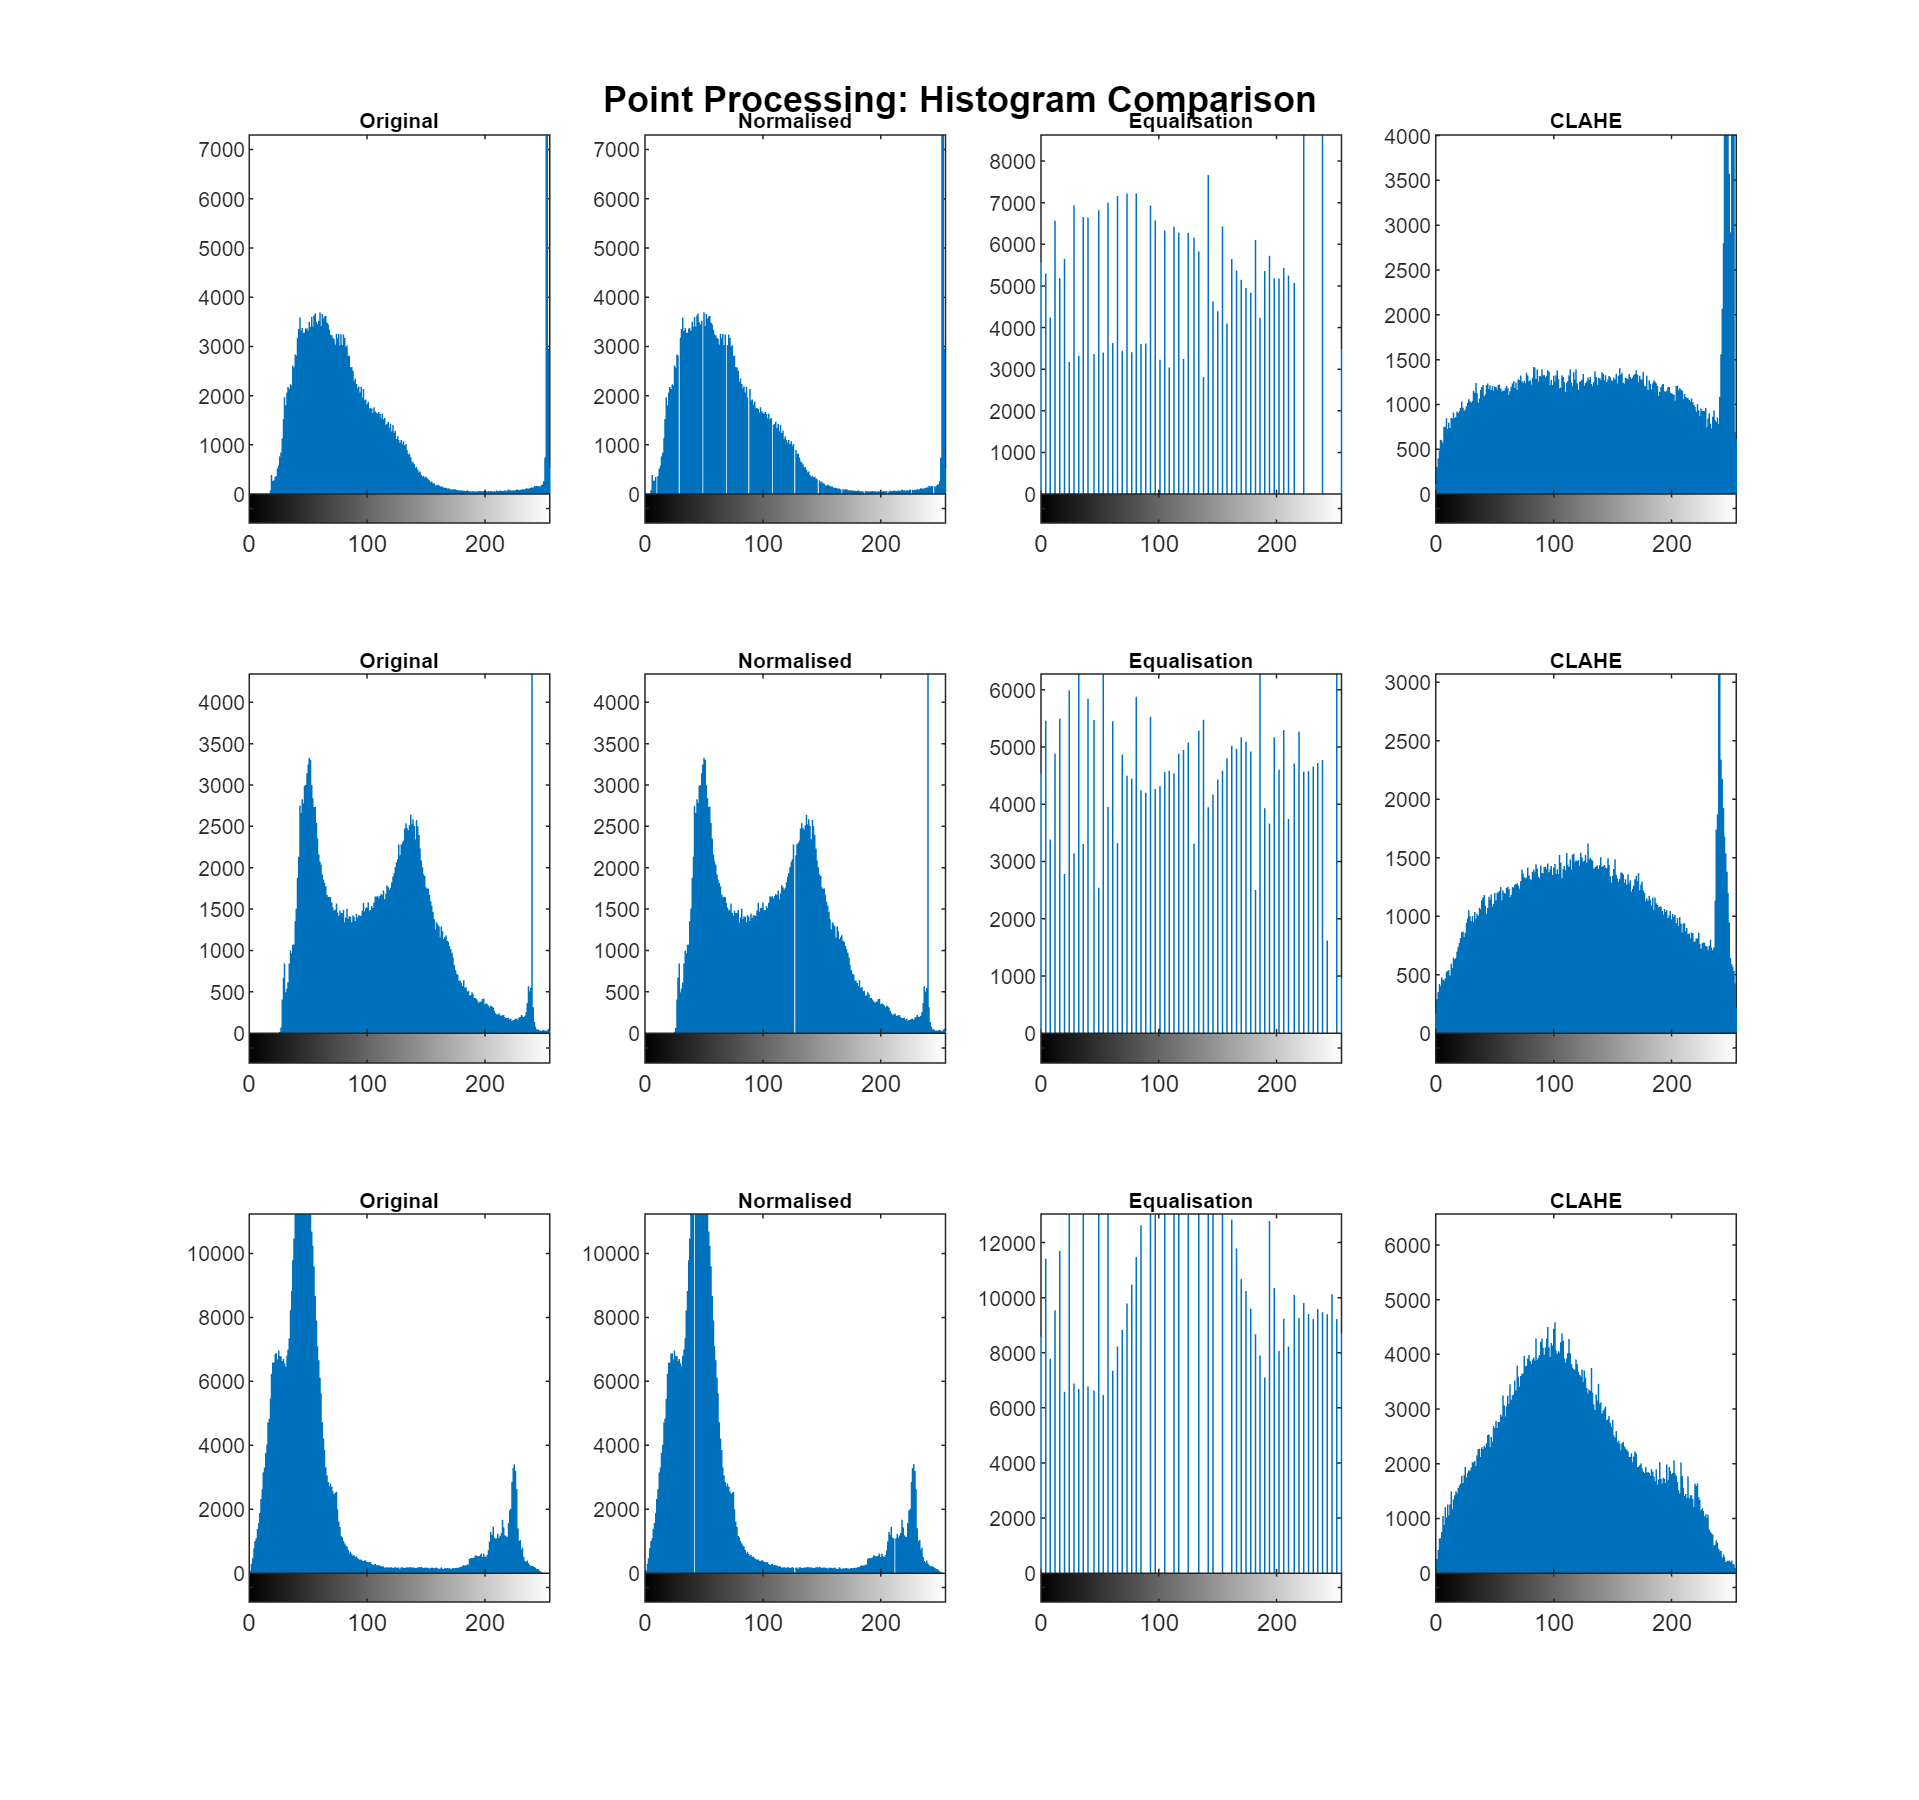


% Plot Histograms
figure('Name', 'Point Processing: Histograms', ...
       'NumberTitle', 'off', 'Position', [0,0,1600,1500]);

for row_disp = 1:length(SELECTED)
    i = SELECTED(row_disp);
    img = images_gray{i};

    % Original
    subplot(length(SELECTED),4,(row_disp-1)*4 + 1);
    imhist(img); set(gca,'FontSize',7);
    title(sprintf('Original'), 'FontSize',7);

    % Normalised
    subplot(length(SELECTED),4,(row_disp-1)*4 + 2);
    imhist(images_norm{i}); set(gca,'FontSize',7);
    title(sprintf('Normalised'), 'FontSize',7);

    % Equalised
    subplot(length(SELECTED),4,(row_disp-1)*4 + 3);
    imhist(images_eq{i}); set(gca,'FontSize',7);
    title(sprintf('Equalisation'), 'FontSize',7);

    % CLAHE
    subplot(length(SELECTED),4,(row_disp-1)*4 + 4);
    imhist(images_clahe{i}); set(gca,'FontSize',7);
    title(sprintf('CLAHE'), 'FontSize',7);
end

sgtitle('Point Processing: Histogram Comparison', ...
        'FontSize',12,'FontWeight','bold');

CLAHE produced the clearest and most consistent contrast enhancement across the dataset. As a result, the rails became significantly more distinguishable from the background, improving their visibility under different conditions. Compared to the other methods, CLAHE better preserved local details while enhancing contrast, making it the most effective approach for this application.

## 1.3. Image Filtering

After contrast enhancement, the next step in the pipeline is image filtering, whose main objective is to reduce noise while preserving relevant structures such as rail edges. Since railway images often contain texture, shadows, and small artifacts, filtering is essential to improve the robustness of subsequent edge and line detection stages.

To evaluate the most suitable approach, three different low-pass filters were tested on a representative subset of five images:

- Averaging filter

- Gaussian filter

- Median filter

These filters aim to smooth the image by attenuating high-frequency components, which are typically associated with noise.

The averaging filter is a simple uniform low-pass filter that replaces each pixel with the mean value of its surrounding neighborhood. The kernel size defines the size of the neighborhood, larger kernels increase smoothing but also increase edge blurring. 

The gaussian filter is a weighted low-pass filte**r** where pixels closer to the center have higher influence, following a Gaussian distribution. This results in smoother noise reduction with better edge preservation. The sigma controls the spread of the Gaussian. Lower values preserve details, while higher values produce stronger smoothing.

The median filter is a non-linear filter that replaces each pixel with the median value of its neighborhood. Larger kernels remove more noise but may distort fine details.

For a first analysis, we assigned a 5×5 kernel for the averaging filter, sigma 1.0 for the Gaussian filter, and a 5×5 neighborhood for the median filter, as these values provide a balanced initial smoothing effect. This configuration allows us to observe the relative impact of each filtering method on the images before fine tuning parameters for optimal contrast enhancement and edge preservation.

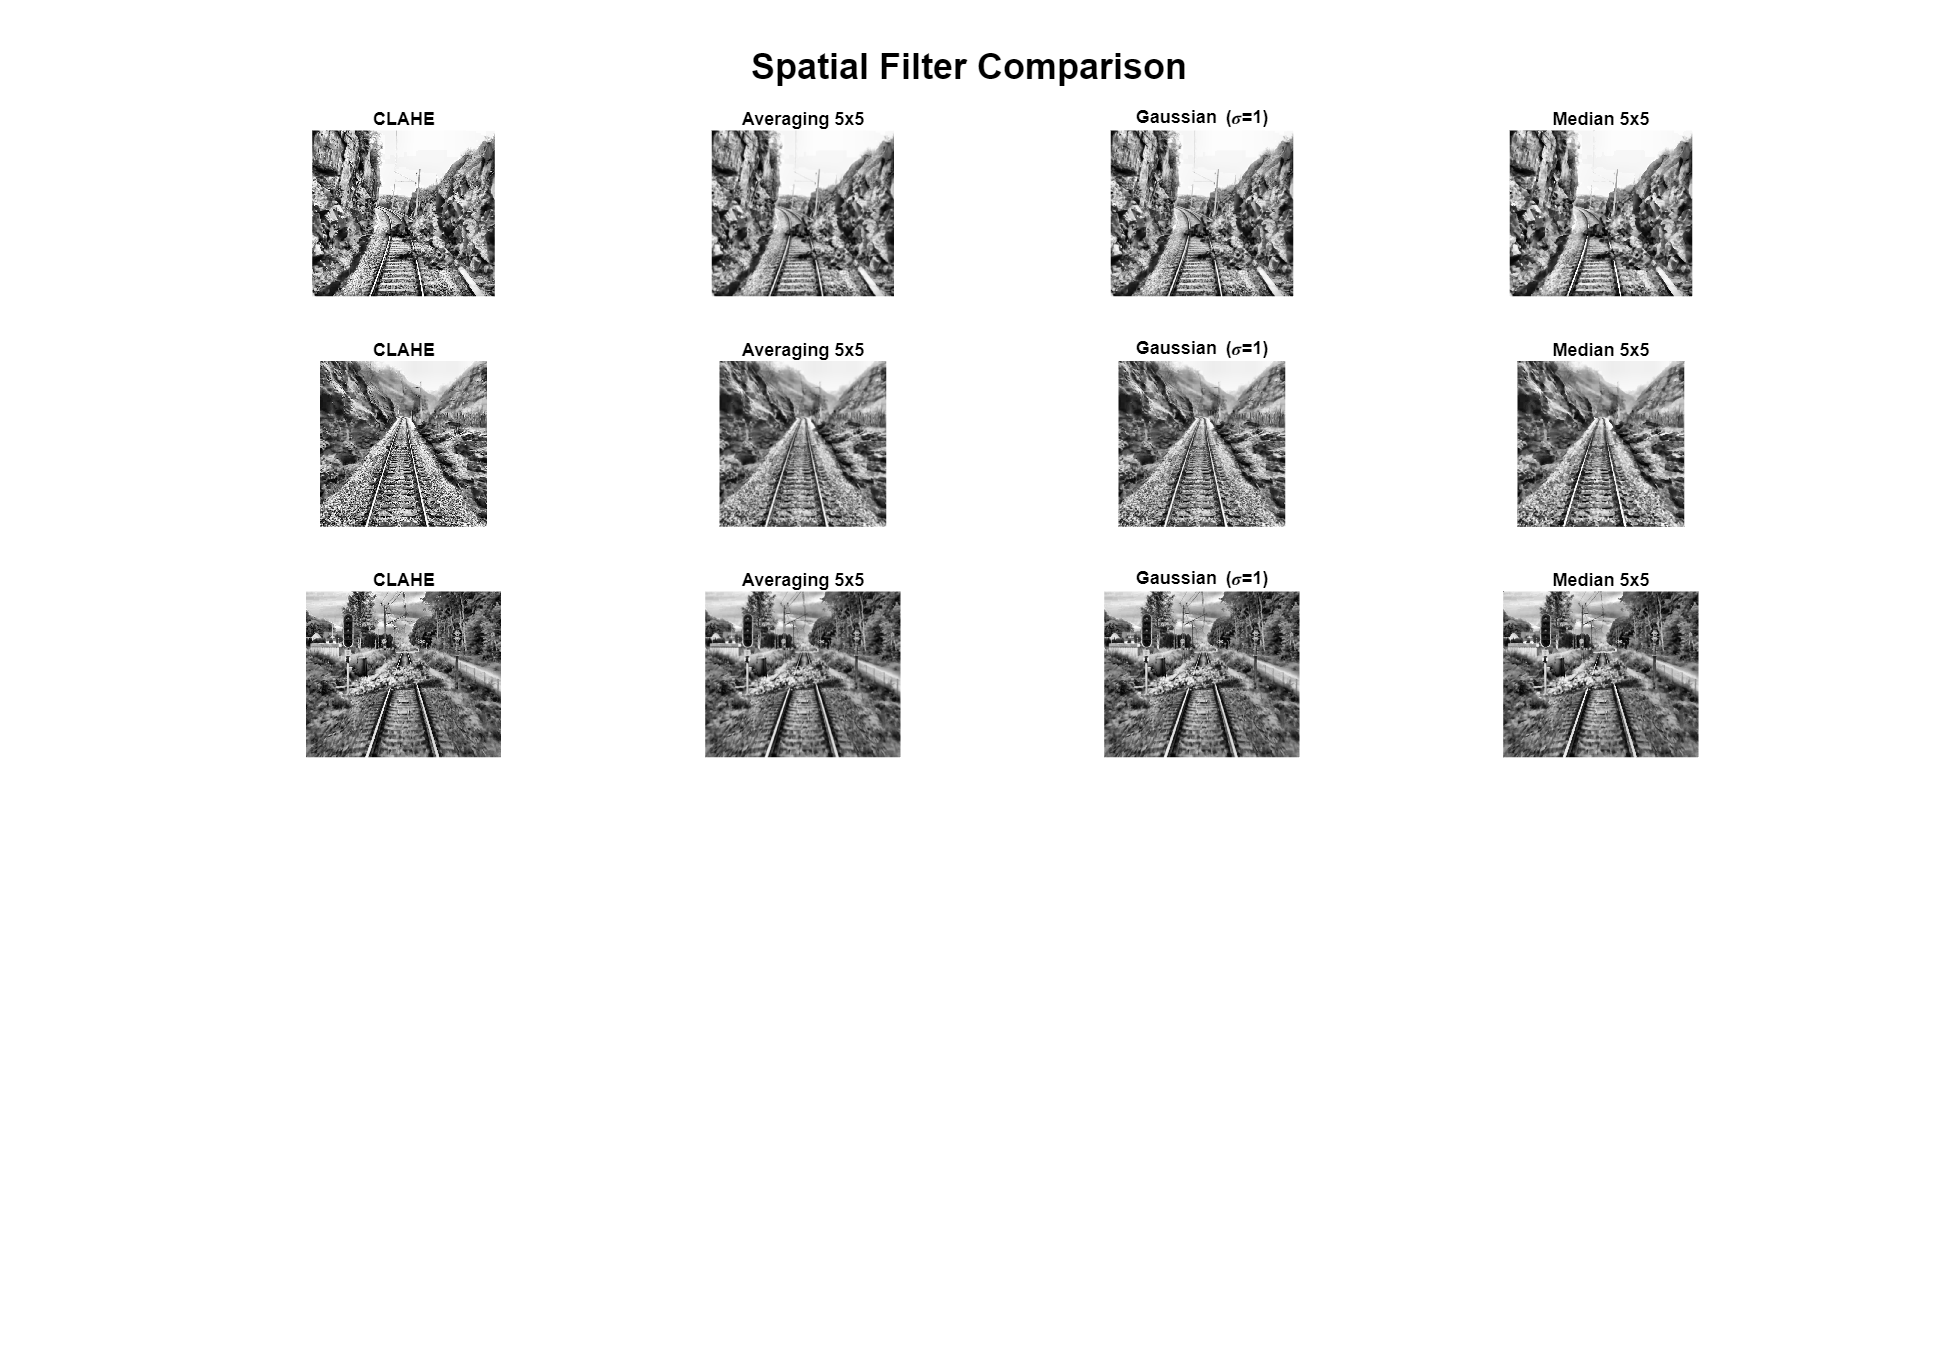

KERNEL_SIZE = 5;
sigma = 1;

figure('Name', 'Figure: Spatial Filter Comparison', ...
    'NumberTitle', 'off', ...
    'Position', [0, 0, 2800, 2400]);

for row = 1:length(SELECTED)
    i   = SELECTED(row);
    img = images_clahe{i};

    % Averaging filter
    h_avg   = fspecial('average', KERNEL_SIZE);
    img_avg = imfilter(img, h_avg, 'replicate');

    % Gaussian filter
    img_gauss = imgaussfilt(img, sigma);

    % Median filter
    img_med = medfilt2(img, [KERNEL_SIZE KERNEL_SIZE]);

    % Plot 
    subplot(5, 4, (row-1)*4 + 1);
    imshow(img);
    title(sprintf('CLAHE'), 'FontSize', 6, 'Interpreter', 'none');

    subplot(5, 4, (row-1)*4 + 2);
    imshow(img_avg);
    title(sprintf('Averaging %dx%d', KERNEL_SIZE, KERNEL_SIZE), 'FontSize', 6);

    subplot(5, 4, (row-1)*4 + 3);
    imshow(img_gauss);
    title('Gaussian (\sigma=1)', 'FontSize', 6);

    subplot(5, 4, (row-1)*4 + 4);
    imshow(img_med);
    title(sprintf('Median %dx%d', KERNEL_SIZE, KERNEL_SIZE), 'FontSize', 6);
end

sgtitle('Spatial Filter Comparison', ...
    'FontSize', 12, 'FontWeight', 'bold');

Although effective at reducing noise, the average filter treats all pixels equally, which leads to significant edge blurring. In our application, this caused the rail boundaries to become less distinct, negatively impacting line detection. The Gaussian filter provides a smoother and more natural blur compared to the averaging filter. It reduces noise effectively while maintaining edge continuity, which is crucial for detecting rail lines. The median filter is particularly effective at removing impulse noise (salt-and-pepper noise) while preserving edges. However, in our dataset the noise was not predominantly impulsive and the filter introduced slight distortions in linear structure. As a result, although edges were preserved, the continuity of rail lines was sometimes degraded.

Therefore, the Gaussian filter was selected as the most suitable method for this application.

## 1.3.1 Gaussian Parameter Optimization

To further refine the performance of the Gaussian filter, different values of the standard deviation, σ, were tested: σ ∈ {0.5, 1, 2, 3}.

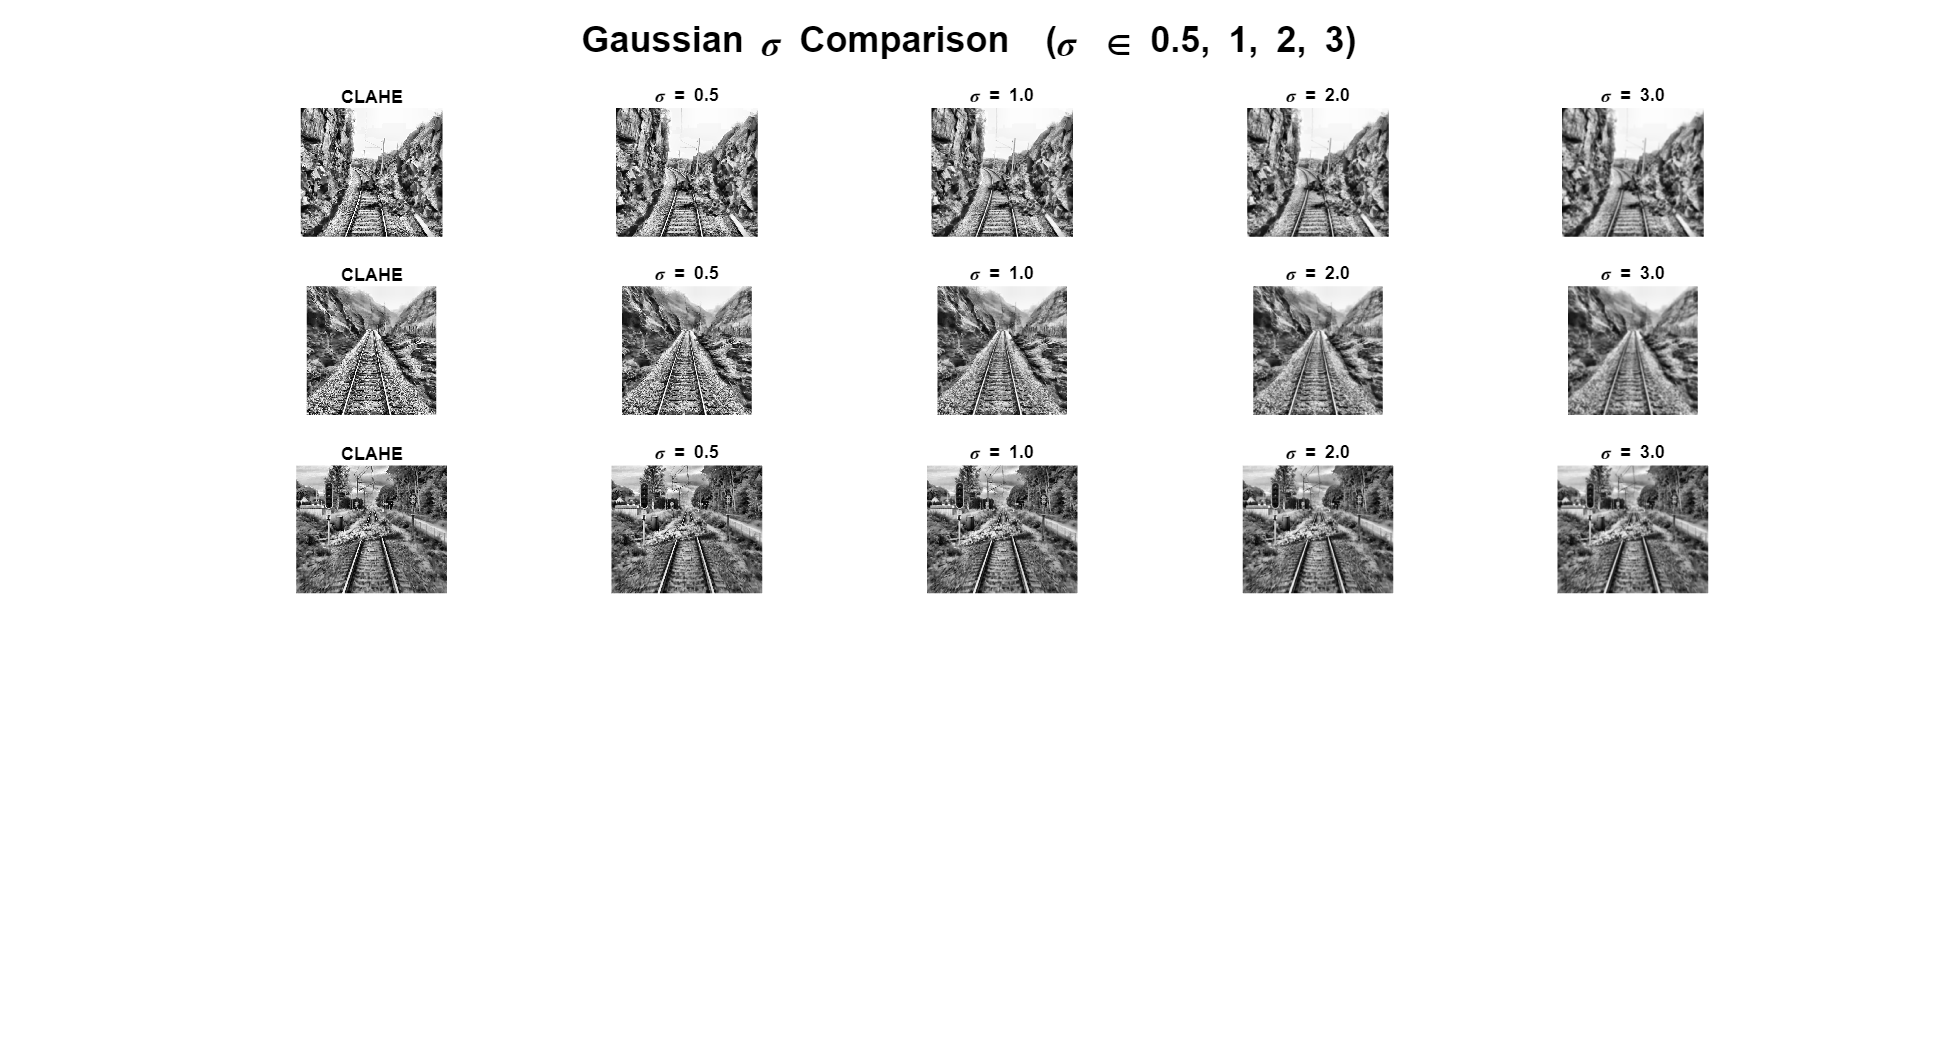

SIGMAS = [0.5, 1, 2, 3];

figure('Name', 'Figure: Gaussian Sigma Comparison', ...
    'NumberTitle', 'off', ...
    'Position', [0, 0, 2000, 1100]);

for row = 1:length(SELECTED)
    i   = SELECTED(row);
    img = images_clahe{i};
    base_title = sprintf('%s', [name ext]);

    % CLAHE input
    subplot(5, 5, (row-1)*5 + 1);
    imshow(img);
    title(sprintf('CLAHE'), ...
        'FontSize', 6, 'Interpreter', 'none');

    % Gaussian sigmas
    for s = 1:length(SIGMAS)
        sigma = SIGMAS(s);
        img_g = imgaussfilt(img, sigma);
        subplot(5, 5, (row-1)*5 + s + 1);
        imshow(img_g);
        title(sprintf('\\sigma = %.1f', sigma), 'FontSize', 6);
    end
end

sgtitle('Gaussian \sigma Comparison  (\sigma \in {0.5, 1, 2, 3})', ...
    'FontSize', 12, 'FontWeight', 'bold');

After evaluating different values of the Gaussian standard deviation, it was observed that small values, such as σ = 0.5, provided insufficient smoothing, leaving noise largely unfiltered. Higher values, including σ = 1.5 and σ = 2, introduced excessive blurring that diminished important rail edge details. A standard deviation of σ = 1 offered the optimal balance, effectively reducing noise while preserving clear and continuous rail edges.

## 1.4. Edge Enhancement

The next phase focused on edge enhancement to improve the visibility of the rails, facilitating more accurate line detection. Two approaches were considered: Unsharp Masking and the Difference of Gaussians (DoG) filter.

Unsharp Masking works by subtracting a blurred version of the image from the original, which emphasizes high-frequency details and sharpens edges. The degree of enhancement can be controlled by adjusting the amount of sharpening and the radius of the Gaussian blur.

The Difference of Gaussians (DoG) filter, which was discussed in theoretical classes as a pre-step for SIFT algorithm, was also evaluated experimentally on our railway images, since it highlights edges making rail boundaries more pronounced while effectively suppressing low-frequency background variations.

The DoG was computed by subtracting a Gaussian-smoothed image with σ₁ from a coarser one with σ₂ = 1.6·σ₁, where the ratio 1.6 was proposed by Marr & Hildreth as the optimal approximation to the Laplacian of Gaussian edge detector. For Unsharp Masking, an amount of 1 was used, meaning the extracted edge signal is added back to the image at full weight, providing a balanced sharpening without over-amplifying noise.

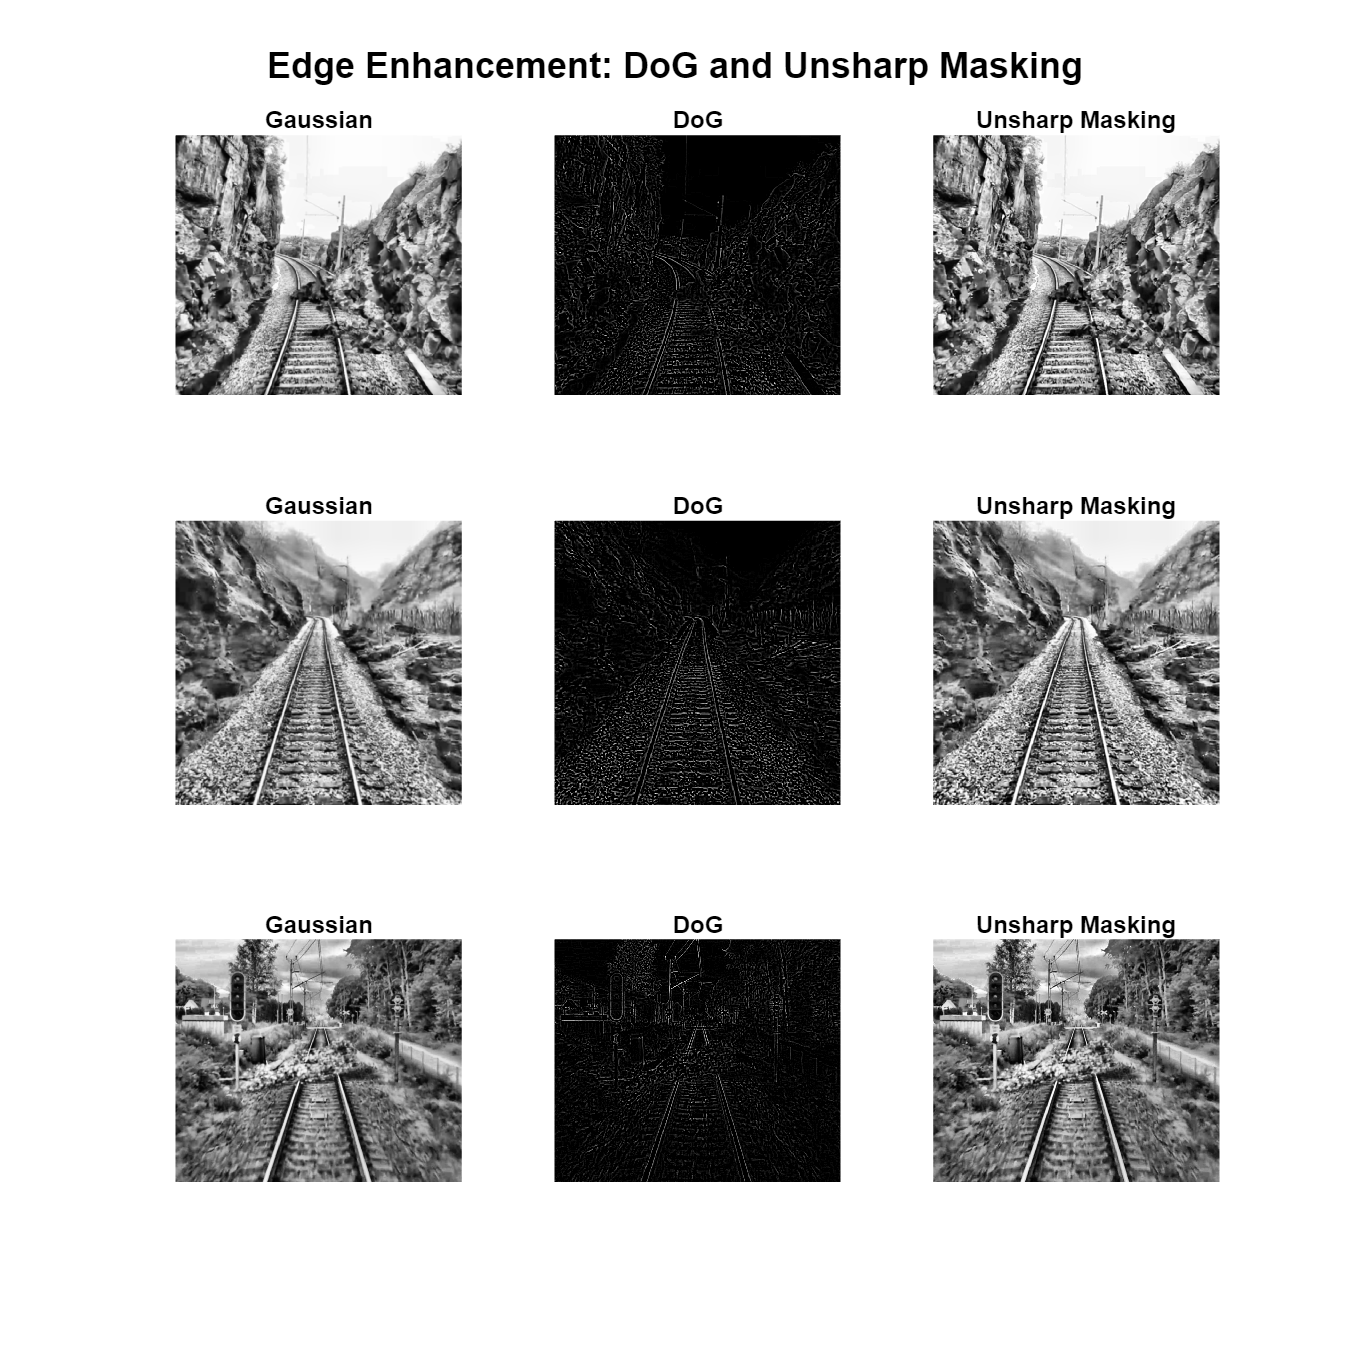

%  Parameters
sigma = 1;

images_gauss = cell(N, 1);
images_dog   = cell(N, 1);
images_us    = cell(N, 1);

for i = 1:N
    img = images_clahe{i};

    % Gaussian
    img_g = imgaussfilt(img, sigma);
    images_gauss{i} = img_g;

    % DoG
    img_g2  = imgaussfilt(img, sigma * 1.6);
    img_dog = imsubtract(img_g2, img_g);
    images_dog{i} = mat2gray(img_dog);

    % Unsharp Mask
    img_us = imsharpen(img_g, 'Radius', sigma, 'Amount', 1);
    images_us{i} = img_us;
end

figure('Name', 'Edge Enhancement', ...
       'NumberTitle', 'off', ...
       'Position', [0, 0, 3*200, length(SELECTED)*200]);

for row_disp = 1:length(SELECTED)
    i = SELECTED(row_disp);

    subplot(length(SELECTED), 3, (row_disp-1)*3 + 1);
    imshow(images_gauss{i});
    title(sprintf('Gaussian'), 'FontSize', 8);

    subplot(length(SELECTED), 3, (row_disp-1)*3 + 2);
    imshow(images_dog{i});
    title(sprintf('DoG'), 'FontSize', 8);

    subplot(length(SELECTED), 3, (row_disp-1)*3 + 3);
    imshow(images_us{i});
    title(sprintf('Unsharp Masking'), 'FontSize', 8);
end

sgtitle('Edge Enhancement: DoG and Unsharp Masking', ...
        'FontSize', 12, 'FontWeight', 'bold');

The DoG filter successfully isolated structural edges, such as rails, rock contours, and vegetation boundaries appearing as bright contours on a dark background. Unsharp Masking, in contrast, preserved the overall image appearance while enhancing edge contrast, yielding a perceptually sharper result. As the differences between methods are hard to compare at this stage, all three will be further evaluated to draw a more informed conclusion on the optimal filter for this dataset.